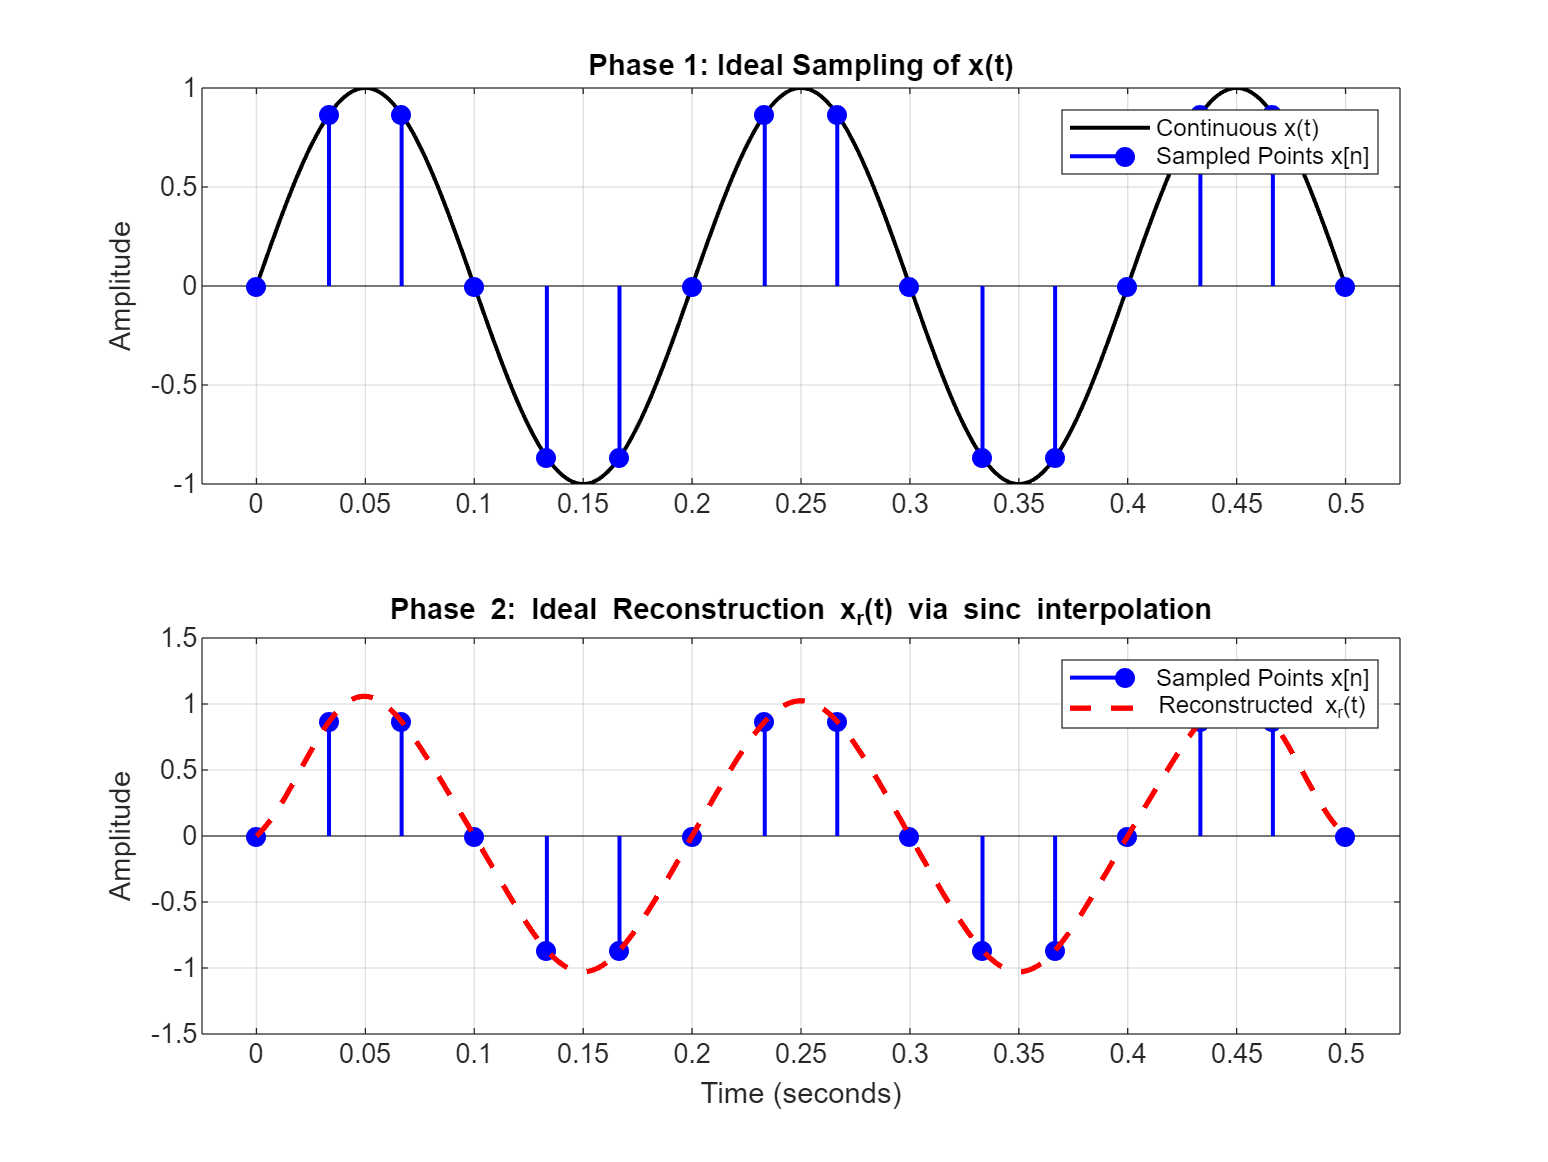

clear  ;
clc;

f_signal=5;
fs=30;
Ts=1/fs;

%High-resolution grid to simulate 'continuous time' t
t_continuous=linspace(0,0.5,1000);
x_continuous=sin(2*pi*f_signal*t_continuous);


%Ideal sampling phase
t_sampled=0:Ts:0.5;
x_sampled=sin(2*pi*f_signal*t_sampled);

%---Ideal Reconstruction Phase (Sinc Interpolation)---
x_reconstructed=zeros(size(t_continuous));

for i=1:length(t_sampled)
    sinc_component=x_sampled(i)*sinc((t_continuous-t_sampled(i))/Ts);
    x_reconstructed=x_reconstructed+sinc_component;
end

figure('Position',[100,100,800,600]);

%Top plot: The original and sampled signal
subplot(2,1,1);
plot(t_continuous,x_continuous,'k-','LineWidth',1.5);hold on;
stem(t_sampled,x_sampled,'b','filled','LineWidth',1.5);
ylabel("Amplitude");
title("Phase 1: Ideal Sampling of x(t)");
legend('Continuous x(t)','Sampled Points x[n]');
grid on;

%Bottom Plot: The restored signal mapped over the old points
subplot(2,1,2);
stem(t_sampled,x_sampled,'b','filled','LineWidth',1.5);hold on;
plot(t_continuous,x_reconstructed,'r--','LineWidth',2);
xlabel("Time (seconds)");
ylabel("Amplitude");
title("Phase 2: Ideal Reconstruction x_r(t) via sinc interpolation");
legend("Sampled Points x[n]","Reconstructed x_r(t)");
grid on ;